%% Define where to look for rosbag files
project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
experiment_name = "feb_2022/helical_3muscle";

%% Parameterize tag locations
% % % ids of tags along the arm (and the order that we will store them in)
experiment_tags = [6 7 8 9 10 11 14 15]; % Tags 6 to 9 
base_tag_id = 10;

% the muscles that these muscles are attached to (in the same order) 
tag_muscle_ids = [2 2 2 2 1 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 0;
t_tags = ([0, 1, 2, 3, 0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 15 20 25 30 35 40 45 50 55 60];
bag_choice = [2 2 2 1 1 1 1 1 2 1 2 1];

%% Parameterize the arm
rho = 0.75 * 0.0254; % M, Radius
muscle_angle = deg2rad(13);
n_muscles = 3;

arm_obj = create_arm_helical(rho, muscle_angle, n_muscles);
arm_obj.n_spacers = 0;

experiment_obj = Experiment(...
    base_tag_id, experiment_tags, tag_muscle_ids, t_tags, arm_obj);

fig = figure();
ax = axes(fig);

mat_h_o_model = zeros(6, length(experiment_pressures));
mat_h_o_fit = zeros(6, length(experiment_pressures));
for i = 1 : length(experiment_pressures)
    subplot(3, 4, i)
    bag = get_tagslam_bag(experiment_name, experiment_pressures(i), bag_choice(i));
    
    [mat_h_o_model(:, i), mat_h_o_fit(:, i)] = ...
        plot_exp_comparison_helical(bag, experiment_pressures(i), experiment_obj);
    title(sprintf("%dpsi", experiment_pressures(i)))
end

Testing with bag: localized-0psi_2022-02-08-21-44-53.bag
Testing with bag: localized-10psi_2022-02-08-21-44-15.bag
Testing with bag: localized-15psi_2022-02-08-21-43-30.bag
Testing with bag: localized-20psi_2022-02-08-21-21-20.bag
Testing with bag: localized-25psi_2022-02-08-21-21-56.bag
Testing with bag: localized-30psi_2022-02-08-21-22-46.bag
Testing with bag: localized-35psi_2022-02-08-21-24-28.bag
Testing with bag: localized-40psi_2022-02-08-21-28-57.bag
Testing with bag: localized-45psi_2022-02-08-21-37-46.bag
Testing with bag: localized-50psi_2022-02-08-21-31-55.bag
Testing with bag: localized-55psi_2022-02-08-21-35-45.bag
Testing with bag: localized-60psi_2022-02-08-21-34-38.bag


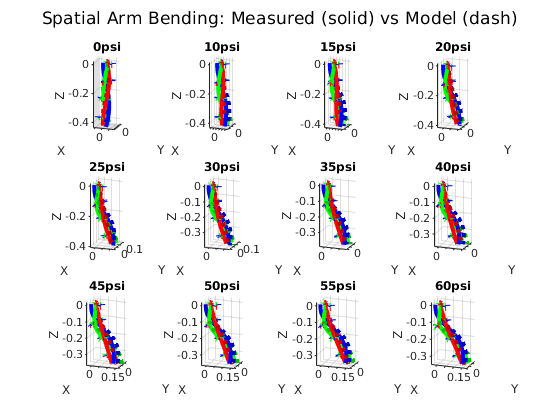

sgtitle("Spatial Arm Bending: Measured (solid) vs Model (dash)")

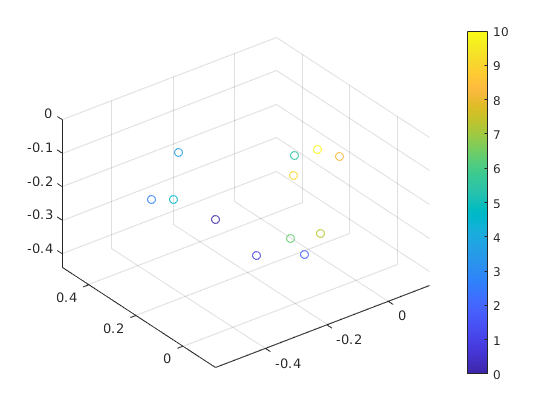

v_diff_h_i = @(i) mat_h_o_fit(i, :) - mat_h_o_model(i, :);

figure()
scatter3(v_diff_h_i(4), v_diff_h_i(5), v_diff_h_i(6), [], linspace(0, 10, length(v_diff_h_i(1))));
%stem3( v_diff_h_i(6), v_diff_h_i(4), v_diff_h_i(5));
colorbar
grid on
axis equal

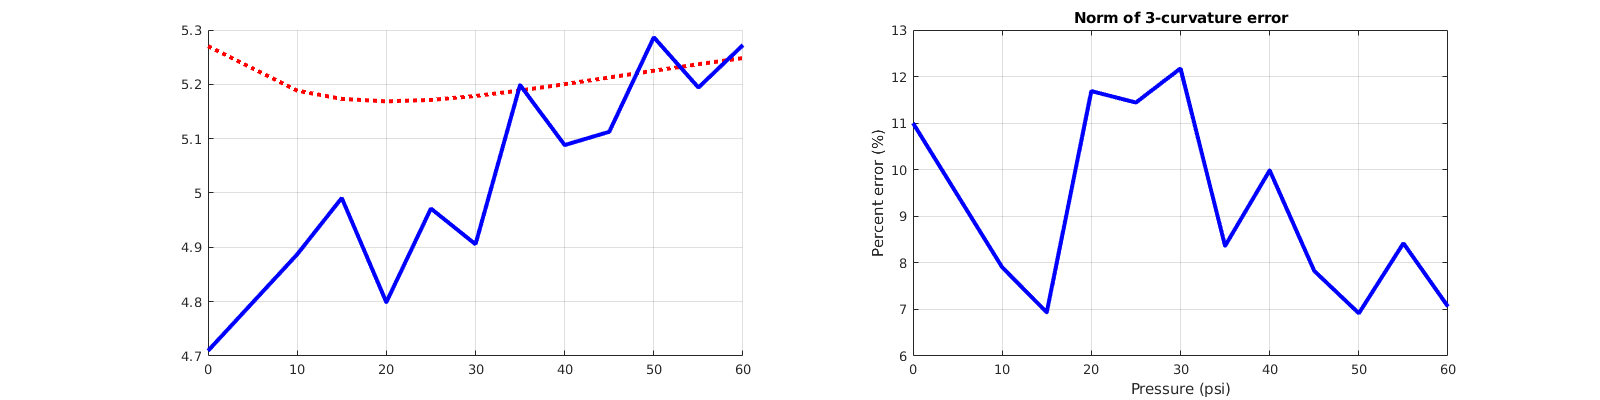

% Curvature error norm
mat_omega_error = mat_h_o_fit(4:6, :) - mat_h_o_model(4:6, :);
v_norm_error = vecnorm(mat_omega_error);
v_norm_meas = vecnorm(mat_h_o_fit(4:6, :));
v_norm_model = vecnorm(mat_h_o_model(4:6, :));
v_percent_error = abs(v_norm_error ./ v_norm_model) * 100;

figure()
set(gcf, 'position', [0 0 1600 400])
subplot(1, 2, 1)
hold on
plot(experiment_pressures, v_norm_model, 'r:', 'linewidth', 3);
plot(experiment_pressures, v_norm_meas, 'b', 'linewidth', 3);
grid on

subplot(1, 2, 2)
plot(experiment_pressures, v_percent_error, 'linewidth', 3, 'color', 'blue');
xlabel("Pressure (psi)")
ylabel("Percent error (%)")
title("Norm of 3-curvature error")
grid on

function model_arm = create_arm_helical(rho, muscle_angle, n_muscles) 
    % Construct pose matrices
    % Transformations from world frame to each muscle
    
    % Base muscle pose: pointing down, located at 0,0,0:
    % The neutral pose is where the main contracting muscle will be. This is
    % our "origin"
    g_origin = SE3(eul2rotm([0, pi/2, 0], 'xyz'), [0 0 0]); % Frame corresponding to a muscle at the origin, pointing down
    
    % Poses of muscle in world frame
    % Muscles are arranged in equilateral triangle with radius rho
    g_muscles = Arm3D.generate_g_muscles(rho, g_origin, n_muscles, muscle_angle);
    
    g_default_muscle = g_muscles{1}; % Default muscle: 
    g_default_muscle(1:3, 4) = zeros(3, 1);
    %g_default_muscle = SE3(eul2rotm([0, pi/2, 0], 'xyz'), [0 0 0]);
    
    % Set position of first muscle to actually be at the origin
    % We want to shift *everything* uniformly regardless of its pose, therefore
    % it'll be a left-action:
    % g_shift * g_1 = g_neutral
    % Therefore g_shift = g_neutral * inv(g_1)
    % Additionally, we rotate by a global 180deg so that all 3 muscles are
    % aligned correctly
    g_muscle_shift = g_default_muscle * inv(g_muscles{1});
    
    % Then left-apply g_shift to all transformations
    g_o = g_muscle_shift * g_origin;
    g_muscles = cellfun(@(g_muscle) g_muscle_shift * g_muscle, g_muscles, 'uniformoutput', false);
    
    model_arm = Arm3D(g_o, g_muscles, contraction_fit(0), 'plot_unstrained', false);
end